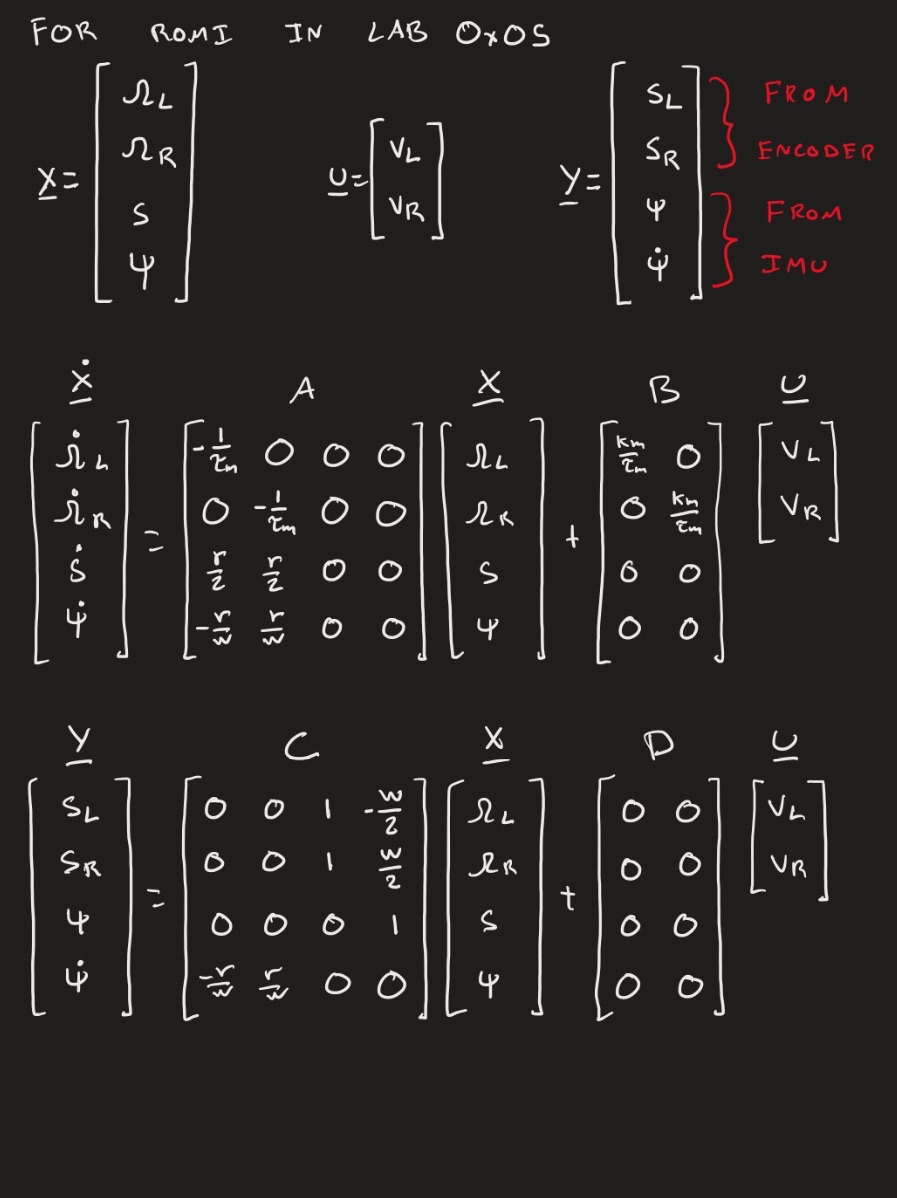


% Electromechanical properties
% K      = 250*2*pi/60/4.5   % Motor Gain [rad/(V*s)]
K = 2.835;
tau    = 0.1            ;   % Motor Time Constant [s]
r      = 35             ;   % Wheel Radius [mm]
w      = 141            ;   % Width between wheels [mm]

speed_multiplier = 10;
T_s = tau/10 ;% Time step in seconds

A = [-1/tau     0       0   0,
      0         -1/tau  0   0,
      r/2       r/2     0   0,
      -r/w      r/w     0   0];
B = [K/tau  0,
     0      K/tau,
     0      0,
     0      0];
C = [0      0       1   -w/2,
     0      0       1   w/2,
     0      0       0   1,
     -r/w   r/w     0   0];
D = zeros([4,2]);

% Create the state-space model object
sys_ss = ss(A, B, C, D);

% Get the poles of the system model
poles = pole(sys_ss);
sped_up_poles = poles.*speed_multiplier;
complex_poles = [-1000 + 200j, -1000 - 200j]

complex_poles = 1.0e+03 *

  -1.0000 + 0.2000i  -1.0000 - 0.2000i


desired_poles = [sped_up_poles(3:4)', complex_poles ]

desired_poles = 1.0e+03 *

  -0.1000 + 0.0000i  -0.1000 + 0.0000i  -1.0000 + 0.2000i  -1.0000 - 0.2000i



L = place(A', C', sped_up_poles)';

L = L.*100

L = 1.0e+04 *

   -0.1286   -0.1286   -0.0000   -1.8129
   -0.1286   -0.1286    0.0000    1.8129
    0.4500    0.4500   -0.0000    0.0000
    0.0000    0.0000    0.0000    0.0100



A_zero = A - L*C;
B_zero = [B- L*D, L];
new_sys = ss(A_zero, B_zero, C, 0);

disc = c2d(new_sys, T_s, 'zoh');
A_d = disc.A;
B_d = disc.B;

% disp(A_d(:));
% disp(B_d(:));
% disp(disc.C(:));

sprintf('%f,', A_d(:))

ans = '0.499445,0.499445,0.001942,0.002727,0.499445,0.499445,0.001942,-0.002727,0.285397,0.285397,0.001110,-0.000000,-0.000000,-0.000000,0.000000,1.000000,'

sprintf('%f,', B_d(:))

ans = '0.143168,0.140021,0.000545,0.000765,0.140021,0.143168,0.000545,-0.000765,-0.142699,-0.142699,0.499445,0.000000,-0.142699,-0.142699,0.499445,0.000000,-0.000000,0.000000,-0.000000,0.000000,-2.012050,2.012050,0.000000,0.022074,'

sprintf('%f,', C(:))

ans = '0.000000,0.000000,0.000000,-0.248227,0.000000,0.000000,0.000000,0.248227,1.000000,1.000000,0.000000,0.000000,-70.500000,70.500000,1.000000,0.000000,'